This is a workbook to learn how to fit a mixed effects model for the pilot data collected from Qualtrics for the EEE study. 

This is not publication quality. It is documenting my learning and thoughts. 

By Ben Graul

% master = readtable('https://raw.githubusercontent.com/ben-g-1/Psyc178/main/pilot_clean.csv');
master = readtable('https://raw.githubusercontent.com/ben-g-1/Psyc178/main/pilot_clean_NaNs.csv');

master.Pair = categorical(master.Pair);
master.Image = categorical(master.Image);
master.subj = categorical(master.subj);
master.val_type = categorical(master.val_type);
master.Half = categorical(master.Half);
master.group = categorical(master.group);
master.img_rate = master.img_rate - 50;
master.exp_rate = master.exp_rate - 50;
master.Valence_mean = master.Valence_mean - 50;

What do the data look like? We care about the rating that participants gave to an image after seeing a cue type. 

hicue_val = (master.img_rate(master.highcue_indx == 1));
locue_val = (master.img_rate(master.highcue_indx == -1));
master.highcue_indx = categorical(master.highcue_indx);


% data_to_plot = {hicue_val, locue_val};
% colors = seaborn_colors(2);
% 
% % create_figure('Violins'); 
% barplot_columns(data_to_plot, 'Cue Effect on Valence Rating', 'colors', colors, 'MarkerSize', 0.5, ...
%     'names', {'Hi Cue', 'Low Cue'});

Col   1: Hi Cue	Col   2: Low Cue	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error      T           P         Cohens_d
    ___________    __________    _________    ______    __________    ________

    {'Hi Cue' }      4.8393       0.48921      9.892    2.2204e-15     0.15767
    {'Low Cue'}     0.65485       0.48407     1.3528        0.1762    0.021563



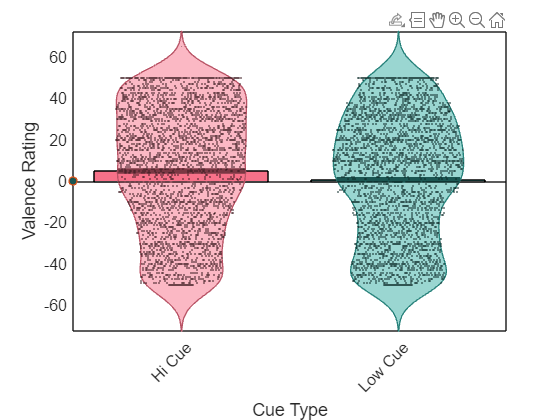

% ylabel('Valence Rating')
% xlabel('Cue Type');
% hold off;

(This takes an extremely long time in a live script- apparently there's a known bug where figures with many points slow live scripts down considerably. It's been crashing my session sometimes though)

**Note on the following: **

**I now know that the p-value comparison of lmes is less important than starting with a theoretically-driven model.**

Let's start off with a very simple regression for predicting the valence score from the normative OASIS valence ratings.

We'll include a positive control for something that should have no relationship with the ratings for a sanity check.  

lme1 = fitlme(master, 'img_rate ~ Valence_mean')

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue    Lower      Upper  
    {'(Intercept)' }        -55.157       0.58831    -93.755    7870    0         -56.311    -54.004
    {'Valence_mean'}         1.0393     0.0097856     106.21    7870    0          1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617      19.313    


badlme = fitlme(master, 'img_rate ~ Half')

badlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Half

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    76205    76226    -38099           76199   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue       Lower      Upper 
    {'(Intercept)'}         2.4754     0.48771     5.0755    7870    3.954e-07     1.5193    3.4314
    {'Half_2'     }        0.54345     0.68973    0.78791    7870      0.43077    -0.8086    1.8955

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        30.598      30.124    31.079


 It looks like there's a strong connection between these subject valence ratings and the OASIS valence ratings. This is not surprising. 

What if we add in the variable of interest? 

lme2 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx');
compare(lme1, lme2); %sig 

This produces a significant improvement.  

Can we improve by adding subjects as a random effect? 

lme3 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1|subj)');
compare(lme2, lme3, 'CheckNesting', true); %sig 

This was also a significant improvement. 

The computing time increases dramatically (seconds vs many minutes) once I start adding in random effects.

What about if we cross the fixed effect as well?

lme4 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (1|subj)')

lme4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           4
    Random effects coefficients        123
    Covariance parameters                2

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68756    68798    -34372           68744   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate     SE          tStat      DF      pValue       Lower        Upper   
    {'(Intercept)'                }          -56.987     0.92578    -61.556    7868            0      -58.802     -55.172
    {'highcue_indx_1'             }           3.6604      1.1273     3.2472    7868    0.0011705       1.4507      5.8701
    {'Valence_mean'               }           1.0347    0.013261     78.025    7868    

compare(lme3, lme4, 'CheckNesting', true); %nosig 

Doesn't seem to have any real benefit. Let's try to account for individual preference of a given image *within* each subject.


lme5 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj)')
compare(lme3, lme5, 'CheckNesting', true); %sig 

So currently, what we're seeing is that the normative valence rating provided with the OASIS set **and** the type of cue provided for a given image both impact the valence rating the participants give. 

Furthermore, a random effect ***crossing each image with each subject*** to estimate personal preference of a given image explains more of the data than just adding the subjects as a random effect. 

Can we see if the *category of cue type* or the *actual average observed in the cue* matter more?

lme6 = fitlme(master, 'img_rate ~ Valence_mean + cue_observed_mean + (1 + Image|subj)');
compare(lme5, lme6, 'CheckNesting', false) % p = 0?

This confused me, because the AIC and BIC are both higher for #6, but the p value is 0. I think this might mean that it can't compute the difference. Let's keep #5 moving forward. 

Another thing we should consider is that while each subject will see the same images, a given image is randomly assigned to be higher or lower than the normative mean. Does accounting for this improve our model?

lme7 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj) + (1 + highcue_indx|Image)');
compare(lme5, lme7, 'CheckNesting', true) % p = 0 again.

We had hypothesized that paired images would be rated similarly within subjects. Is this true?

lme8 = fitlme(master, 'img_rate ~ Valence_mean + cue_observed_mean + (1 + Pair|subj) +  (1 + highcue_indx|Image)');

% lme8 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj) + (1 + highcue_indx|Pair)')
compare(lme8, lme7, 'CheckNesting', false) % p = 0; 5 is still best



The `image pair x subj` interaction was not a significant improvement. That's a bit disappointing, and makes me wonder if the image pairs will actually be that helpful for comparisons. 

bestlme = lme5

What does this look like right now?

F = fitted(bestlme);
R = response(bestlme);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 

figure();
plotResiduals(bestlme, 'fitted')

Do we care about the ratings, or do we actually care about the *difference between *pairs of ratings?

Let's create a table focused on within-pair comparisons

master = sortrows(master,"Pair","ascend");

cuehl = master.highcue_indx;
cuemean = master.cue_observed_mean;
pair = master.Pair;
rating = master.img_rate;
stimmean = master.Valence_mean;

wh_high = cuehl == "1";
wh_low = cuehl == "-1";

hi_table = master(wh_high, :);
lo_table = master(wh_low, :);

pair_table = table();
pair_table.subj = hi_table.subj;
pair_table.Pair = hi_table.Pair;
pair_table.group = hi_table.group;
pair_table.hi_val = hi_table.img_rate;
pair_table.lo_val = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_val - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_val - pair_table.rating_mean;


What do these data look like?

[h,p,ci,stats] = ttest(pair_table.rating_diff)

h = 1

p = 2.1843e-48

ci =     3.6680
    4.7864


stats = struct with fields:
    tstat: 14.8216
       df: 3881
       sd: 17.7699


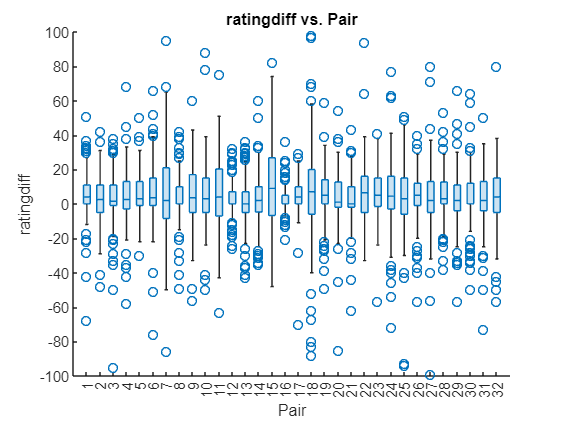


% Create boxchart of pair_table.Pair and pair_table.rating_diff
h1 = boxchart(pair_table.Pair,pair_table.rating_diff,"DisplayName","rating_diff");

% Add xlabel, ylabel, title, and legend
xlabel("Pair")
ylabel("ratingdiff")
title("ratingdiff vs. Pair")

It seems like outliers might be really messing this up. 

**Note: It looks like the barplot_columns function has outlier detection as well.**

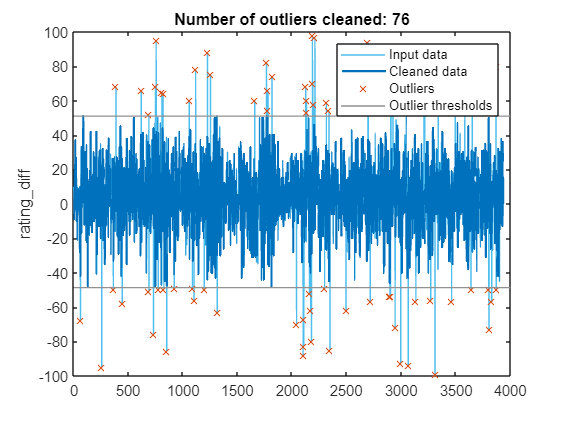

% Remove outliers
[cleanpairs,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(pair_table,...
    "percentiles",[1 99],"DataVariables","rating_diff");

% Display results
figure
plot(pair_table.rating_diff,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanpairs.rating_diff,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),pair_table.rating_diff(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")

% Plot outlier thresholds
plot([xlim missing xlim],...
    [thresholdLow.rating_diff*[1 1] NaN thresholdHigh.rating_diff*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
ylabel("rating_diff","Interpreter","none")

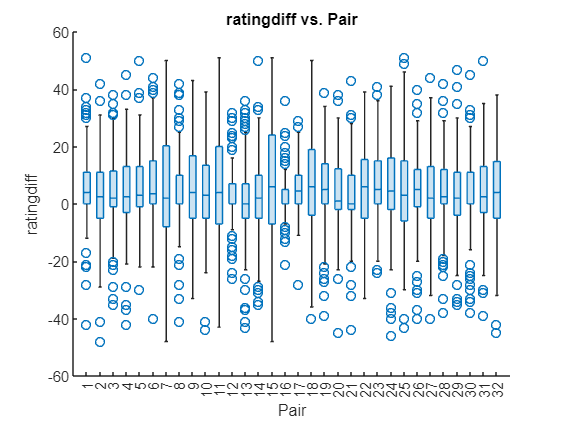

clear thresholdLow thresholdHigh

% Create boxchart of pair_table.Pair and pair_table.rating_diff
h2 = boxchart(cleanpairs.Pair, cleanpairs.rating_diff,"DisplayName","rating_diff");

% Add xlabel, ylabel, title, and legend
xlabel("Pair")
ylabel("ratingdiff")
title("ratingdiff vs. Pair")


[h,p,ci,stats] = ttest(cleanpairs.rating_diff)

h = 1

p = 1.8975e-66

ci =     3.8202
    4.7804


stats = struct with fields:
    tstat: 17.5616
       df: 3805
       sd: 15.1067


How do the LMEs compare for the difference between ratings within pair to the overall valence rating prediction?

lme10 = fitlme(cleanpairs, 'rating_diff ~ stim_mean')

lme11 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (1|subj)')
lme11 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (1|Pair)')
lme12 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (subj|Pair)')

lme12 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (Pair|subj)')

% lme12 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + stim_sd + (Pair|subj)')

% bestlme

The residual error and AIC/BIC are all much lower when looking at the rating difference. This seems like a good thing..?

F = fitted(lme12);
R = response(lme12);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 

figure();
plotResiduals(lme12, 'fitted')

We see less of an obviuos pattern in these residuals as well. There's an odd line around 0 for both of these right now though. 

Questions:

How can I  verify the model accuracy?

Would trying to make a predictive model for some participants left out be a good next step?

Will this be useful to apply to my patient population by adding in iEEG signal?

Michael told me that I should use the 'REML' fitting method, and then correct the degrees of freedom using the Satterthwaite method. 

minlmm = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj)', 'FitMethod', 'REML')

minlmm = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           6
    Random effects coefficients        738
    Covariance parameters               22

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67372    67567    -33658           67316   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE           tStat       DF      pValue         Lower         Upper     
    {'(Intercept)'                  }            -3.7665      0.91191     -4.1303    7807     3.6602e-05       -5.5541       -1.9789
    {'highcue_indx_1'               }             4.3686 

anova(minlmm, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                     FStat      DF1    DF2       pValue    
    {'(Intercept)'                  }          17.06    1      123.38    6.6256e-05
    {'highcue_indx'                 }          42.26    1      869.85    1.3453e-10
    {'Valence_mean'                 }         1455.8    1      123.36    3.7984e-70
    {'highcue_indx:Valence_mean'    }        0.61212    1      2250.1       0.43407
    {'Valence_mean^2'               }         7.9943    1      114.44     0.0055406
    {'highcue_indx:(Valence_mean^2)'}        0.21828    1        1448       0.64042



minlmm2 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair)', 'FitMethod', 'REML')

minlmm2 = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           6
    Random effects coefficients        770
    Covariance parameters               23

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    66812    67013    -33377           66754   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate      SE           tStat       DF      pValue        Lower         Upper    
    {'(Intercept)'                  }           -3.5823       1.8466     -1.9399    7807      0.052427       -7.2022       0.0376
    {'highcue_indx_1'               }            

anova(minlmm2, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                     FStat      DF1    DF2       pValue    
    {'(Intercept)'                  }         3.7632    1      41.171      0.059262
    {'highcue_indx'                 }         46.802    1      1249.2    1.2269e-11
    {'Valence_mean'                 }         364.52    1      37.649    5.8534e-21
    {'highcue_indx:Valence_mean'    }        0.66709    1      2364.6       0.41415
    {'Valence_mean^2'               }         1.4587    1      35.344       0.23515
    {'highcue_indx:(Valence_mean^2)'}        0.23414    1      1734.4       0.62853


When you don't account for pair, the squared term for the valence is significant.

This was made after discussion w/ Tor 10/2/23. 

(The first version did not have highcue_indx as a categorical variable. However, it did have the normative mean as a mean-centered value. This has been fixed.)

This takes a LONG time to run.

torlmm = fitlme(master, 'img_rate ~ highcue_indx + Valence_mean + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx + (highcue_indx + Valence_mean + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

torlmm = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67212    67421    -33576           67152   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat      DF      pValue        Lower         Upper    
    {'(Intercept)'                  }            -3.7919        1.7585    -2.1563    7866      0.031088       -7.2389     -0.34477
    {'highcue_indx_1'        

anova(torlmm, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                     FStat      DF1    DF2       pValue    
    {'(Intercept)'                  }         4.6498    1      49.071      0.035986
    {'highcue_indx'                 }         48.293    1      825.63    7.4525e-12
    {'Valence_mean'                 }          417.1    1      49.869    7.1041e-26
    {'highcue_indx:Valence_mean'    }        0.65219    1      1825.9       0.41944
    {'Valence_mean^2'               }         1.2603    1      38.469       0.26855
    {'highcue_indx:(Valence_mean^2)'}        0.31506    1      1677.2       0.57467


Looking into notation, this can actually be simplified significantly to 

'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)'

because A*B has an implicit A + B, and A^2 includes both A and A^2

Let's check to see if that's right and that it's actually identical 

minlmm3 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

% compare(torlmm, minlmm3)
anova(minlmm3, 'dfmethod', 'satterthwaite')

Yes, these are the same.

 

grouplmm = fitlme(master, 'img_rate ~ Valence_mean* highcue_indx + group + (Valence_mean * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

grouplmm = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           7
    Random effects coefficients        588
    Covariance parameters               13

Formula:
    img_rate ~ 1 + group + highcue_indx*Valence_mean + (1 + highcue_indx*Valence_mean | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    66836    66975    -33398           66796   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate     SE          tStat        DF      pValue        Lower        Upper   
    {'(Intercept)'                }          -5.9258      1.4009      -4.2301    7806    2.3628e-05      -8.6719     -3.1797
    {'group_2'                    }        -0.043734      1.4425    -0.030318    7806       0.97581      -2.8714       2.784
    

anova(grouplmm, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                 FStat      DF1    DF2       pValue    
    {'(Intercept)'              }         17.894    1      102.26    5.1007e-05
    {'group'                    }         2.4855    3      119.15      0.063981
    {'highcue_indx'             }          109.4    1      144.82    2.0159e-19
    {'Valence_mean'             }         421.04    1      61.609    3.1278e-29
    {'highcue_indx:Valence_mean'}        0.54944    1        5673       0.45858


But what is the quadratic doing?

noquadlmm = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (Valence_mean * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

noquadlmm = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           4
    Random effects coefficients        588
    Covariance parameters               13

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 + highcue_indx*Valence_mean | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    66844    66962    -33405           66810   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate    SE          tStat      DF      pValue        Lower        Upper   
    {'(Intercept)'                }          -5.227      1.1118    -4.7014    7809    2.6275e-06      -7.4064     -3.0476
    {'highcue_indx_1'             }          4.1185     0.39379     10.458    7809    1.9733e-25       3.3465      4.8904
    {'Valence_mean' 

anova(noquadlmm, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                 FStat      DF1    DF2       pValue    
    {'(Intercept)'              }         22.104    1      51.137    1.9917e-05
    {'highcue_indx'             }         109.38    1      144.02     2.141e-19
    {'Valence_mean'             }          421.1    1      61.608    3.1182e-29
    {'highcue_indx:Valence_mean'}        0.54553    1      5860.3       0.46018


% compare(minlmm3, noquadlmm)
beep on
beep 
beep

It seems like the quadratic term is actually complicating things once the scale is centered on zero. The AIC and BIC are lower without it included. 

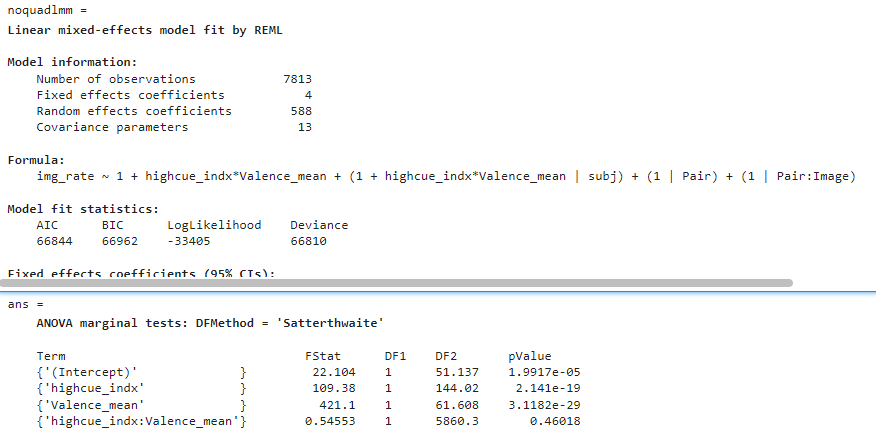

Can we do a permutation test to see if the significance stays after we shuffle the labels?

masterdummy = master;
rows = randperm(size(masterdummy, 1));
masterdummy.highcue_indx = masterdummy.highcue_indx(rows,1);

permlmm = fitlme(masterdummy, 'img_rate ~ Valence_mean * highcue_indx + (Valence_mean * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

permlmm = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           4
    Random effects coefficients        588
    Covariance parameters               13

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 + highcue_indx*Valence_mean | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    66962    67080    -33464           66928   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate    SE          tStat      DF      pValue        Lower        Upper    
    {'(Intercept)'                }         -3.3105      1.1297    -2.9304    7809      0.003395       -5.525       -1.096
    {'highcue_indx_1'             }         0.28757     0.40092    0.71727    7809       0.47323     -0.49835       1.0735
    {'Valence_mean'

anova(permlmm, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                 FStat      DF1    DF2       pValue    
    {'(Intercept)'              }         8.5873    1      54.293     0.0049434
    {'highcue_indx'             }        0.51448    1      2789.9       0.47327
    {'Valence_mean'             }         447.22    1      59.715    2.0163e-29
    {'highcue_indx:Valence_mean'}         2.8245    1      2077.8      0.092987


This removes the significance of highcue_indx

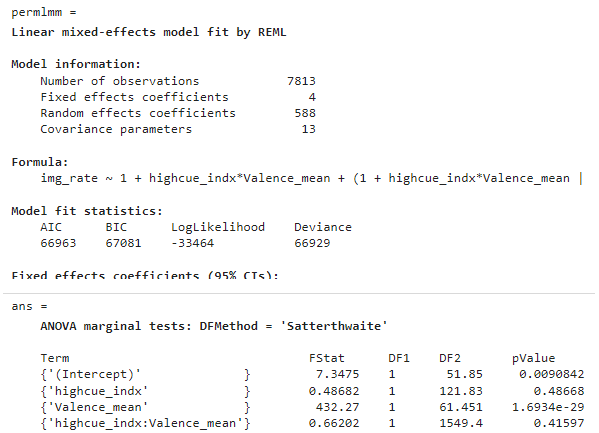

masterdummy.Valence_mean = masterdummy.Valence_mean(rows,1);
permlmm2 = fitlme(masterdummy, 'img_rate ~ Valence_mean * highcue_indx + (Valence_mean * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

permlmm2 = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           4
    Random effects coefficients        588
    Covariance parameters               13

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 + highcue_indx*Valence_mean | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67970    68089    -33968           67936   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate     SE          tStat       DF      pValue     Lower        Upper   
    {'(Intercept)'                }           2.8933      4.3488     0.66532    7809    0.50587      -5.6314      11.418
    {'highcue_indx_1'             }        -0.076096     0.43796    -0.17375    7809    0.86207     -0.93461     0.78242
    {'Valence_mean'     

anova(permlmm2, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                 FStat       DF1    DF2       pValue 
    {'(Intercept)'              }         0.44265    1      31.991    0.51061
    {'highcue_indx'             }        0.030189    1       158.8    0.86228
    {'Valence_mean'             }          1.1164    1      956.91    0.29096
    {'highcue_indx:Valence_mean'}         0.31067    1       721.6    0.57744


lmm4 = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        802
    Covariance parameters               25

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 + highcue_indx | Pair)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67298    67514    -33618           67236   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat       DF      pValue        Lower         Upper    
    {'(Intercept)'                  }            -3.6483        1.7342     -2.1038    7866       0.03543       -7.0478     -0.24888
    {'highcue_indx_1'            



lmm4 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (highcue_indx| Pair)', 'FitMethod', 'REML')
compare(minlmm3, lmm4)

ans =     Theoretical Likelihood Ratio Test

    Model      DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    minlmm3    30    67212    67421    -33576                                
    lmm4       31    67298    67514    -33618    -83.427    1          1     



anova(lmm4, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                     FStat      DF1    DF2       pValue    
    {'(Intercept)'                  }         4.4259    1      50.221      0.040427
    {'highcue_indx'                 }         47.523    1      907.86    1.0169e-11
    {'Valence_mean'                 }         415.76    1      47.475    3.9777e-25
    {'highcue_indx:Valence_mean'    }         0.5202    1      1662.3       0.47086
    {'Valence_mean^2'               }           1.57    1      41.398       0.21723
    {'highcue_indx:(Valence_mean^2)'}        0.29414    1      1603.9       0.58766


Might run out the DF, but maybe (highcue_indx:Image|Pair:subj)? or (highcue_indx:Pair|Pair:subj). These might be nonsensical because the response within pair might be not as consistent as we'd hoped

lmm5 = fitlme(master, 'img_rate ~ Valence_mean^2 + highcue_indx + Pair + (highcue_indx + Valence_mean^2 |subj)', 'FitMethod', 'REML')

lmm5 = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7872
    Fixed effects coefficients          35
    Random effects coefficients        492
    Covariance parameters               11

Formula:
    img_rate ~ 1 + highcue_indx + Pair + Valence_mean + Valence_mean^2 + (1 + highcue_indx + Valence_mean + Valence_mean^2 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67114    67435    -33511           67022   

Fixed effects coefficients (95% CIs):
    Name                      Estimate      SE           tStat       DF      pValue        Lower        Upper   
    {'(Intercept)'   }            1.1759       4.7633     0.24686    7837       0.80502      -8.1614      10.513
    {'highcue_indx_1'}            4.1691       0.3845      10.843    7837     3.353e-27       3.4154      4.9229
    {'Pair_2'        }          -0.8087

compare(minlmm3, lmm5);

anova(lmm5, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                      FStat       DF1    DF2       pValue     
    {'(Intercept)'   }        0.060941     1     7459.3        0.80502
    {'highcue_indx'  }          117.57     1     397.73     3.5647e-24
    {'Pair'          }          23.146    31     7415.3    1.7547e-124
    {'Valence_mean'  }           3.003     1     7503.7        0.08315
    {'Valence_mean^2'}         0.24365     1     7238.6         0.6216


This has 'better fit', but doesn't account for Pair as a random effect. 

I don't know about the quadratic term. How does it change?

lmm6 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:highcue_indx)', 'FitMethod', 'REML')

lmm6 = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:highcue_indx)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67296    67505    -33618           67236   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat       DF      pValue        Lower         Upper    
    {'(Intercept)'                  }             -3.652        1.7282     -2.1132    7866      0.034614       -7.0396     -0.26432
    {'highcue_indx_1' 


compare(minlmm3, lmm6)

ans =     Theoretical Likelihood Ratio Test

    Model      DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    minlmm3    30    67212    67421    -33576                               
    lmm6       30    67296    67505    -33618    -83.46    0          0     



anova(lmm6, 'dfmethod', 'satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                                     FStat      DF1    DF2       pValue    
    {'(Intercept)'                  }         4.4657    1      54.382      0.039187
    {'highcue_indx'                 }         47.615    1      948.58    9.4745e-12
    {'Valence_mean'                 }          418.4    1      51.116    2.8489e-26
    {'highcue_indx:Valence_mean'    }         0.5187    1      1911.8       0.47148
    {'Valence_mean^2'               }         1.5758    1      45.105       0.21583
    {'highcue_indx:(Valence_mean^2)'}        0.29905    1      1819.9       0.58454


The original Qualtrics data has a number of missing measurements that were interpolated using a sliding window. What does it look like if we don't interpolate them?

lmm3nan = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)', 'FitMethod', 'REML')

lmm3nan = Linear mixed-effects model fit by REML

Model information:
    Number of observations            7813
    Fixed effects coefficients           6
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    66730    66939    -33335           66670   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat       DF      pValue        Lower         Upper    
    {'(Intercept)'                  }            -3.7507        1.7895     -2.0959    7807      0.036125       -7.2586     -0.24269
    {'highcue_indx_1'     

What about the provided expectation rating? Does it matter?

explmm = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image) + (1 | exp_rate:Image)')

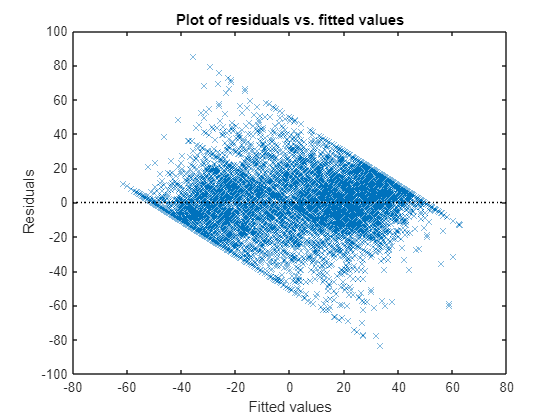



F = fitted(minlmm);
R = response(minlmm);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 


figure();
plotResiduals(minlmm, 'fitted')


% lmmfull = fitlme(master, 'img_rate ~ highcue_indx + Valence_mean + Pair*highcue_indx + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx + (Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)')
